# Example: how to use the internal Gravity Wave Spectrum function

### Define parameters: latitude, stratification, local depth

%Stratification
N0 = 3*2*pi/3600;
L_gm = 1300;
N2Func = @(z) N0*N0*exp(2*z/L_gm);
latitude=33;

%Depth
Lz=4000;       

### Initialize the function

%profile on
im = InternalGravityWaveSpectrum(N2Func,Lz,nModes=64);1

### Vertical Variance

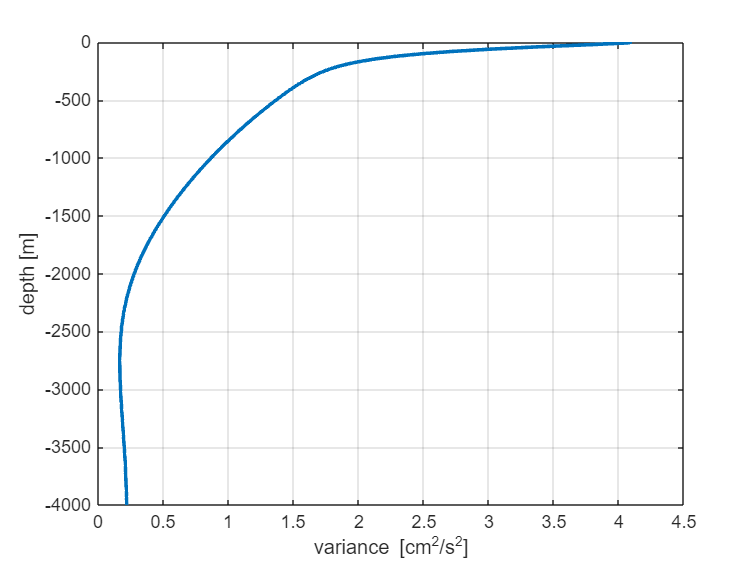

zvect=linspace(-im.Lz,0,1000);
verticalVariance=im.verticalVariance('HKE','zVector',zvect,plot=0);

clf
plot(verticalVariance*1000,zvect,LineWidth=2)
grid on
ylabel("depth [m]")
xlabel("variance [cm^2/s^2]")

### Horizontal Wavenumber Spectrum

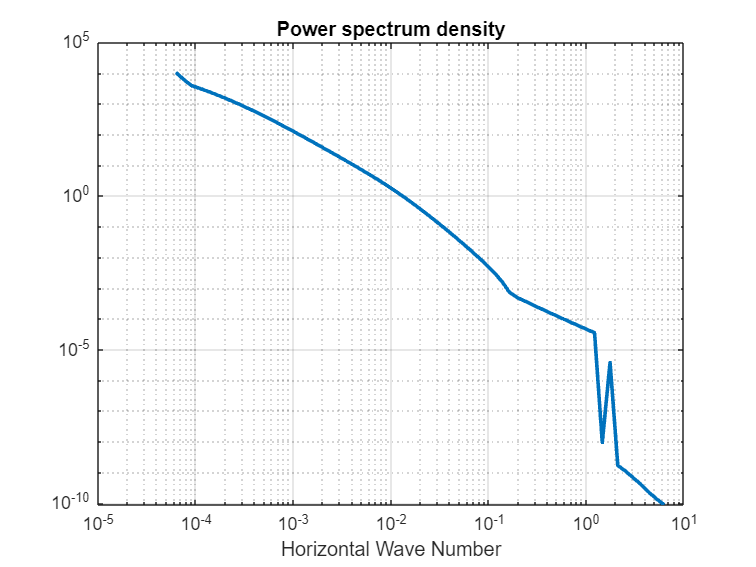

z=-1000;
HorizontalWavenumberSpectrum = im.energyAtHorizontalWavenumber(z,'TE',plot=0);

clf
loglog(im.KRadialLog,HorizontalWavenumberSpectrum*1000,LineWidth=2)
grid on
set(gca,'xscale','log')
title('Power spectrum density')
xlabel('Horizontal Wave Number')

### Frequency Spectrum

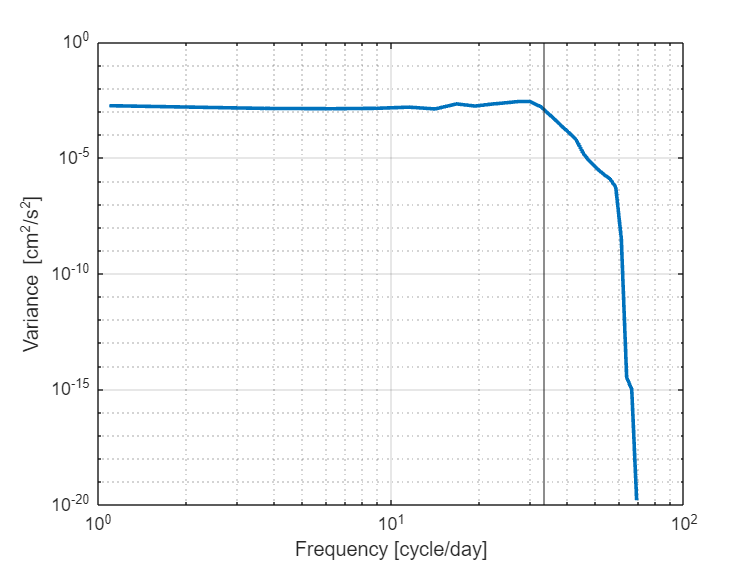

[S,~]=im.energyAtFrequencies('VKE',z,plot=0);

clf
loglog((im.omegaVector)*(24*3600)/(2*pi), S*1000,LineWidth=2)
hold on
xline((sqrt(im.N2(z))*24*3600)/(2*pi),'HandleVisibility', 'off');
ylabel("Variance [cm^2/s^2]")
xlabel("Frequency [cycle/day]")
grid on